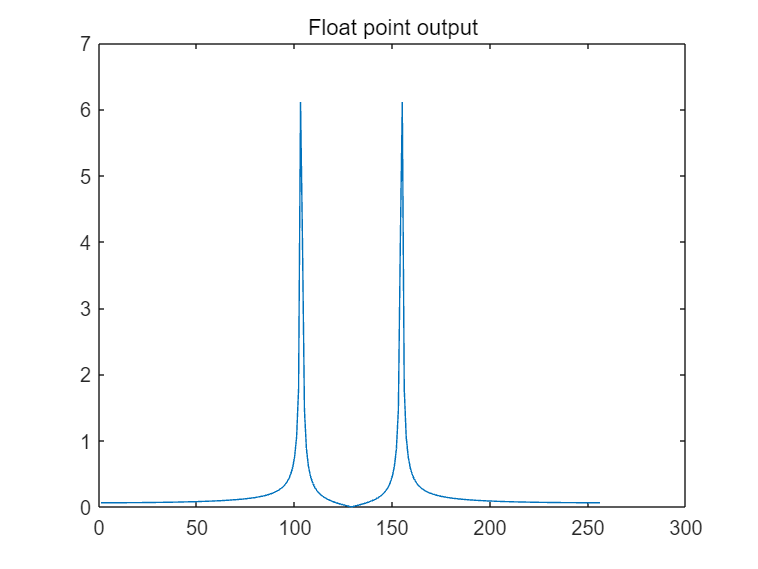

fft_output = importdata('fft_output_3.txt');

real_part = fft_output.data(:,1);
imag_part = fft_output.data(:,2);
fixed16_real = fft_output.data(:,3);
fixed16_imag = fft_output.data(:,4);
s = real_part + i*imag_part;
fix_s = fixed16_real + i*fixed16_imag;
x = 1:length(s);
plot(x,fftshift(abs(s)))
title("Float point output")

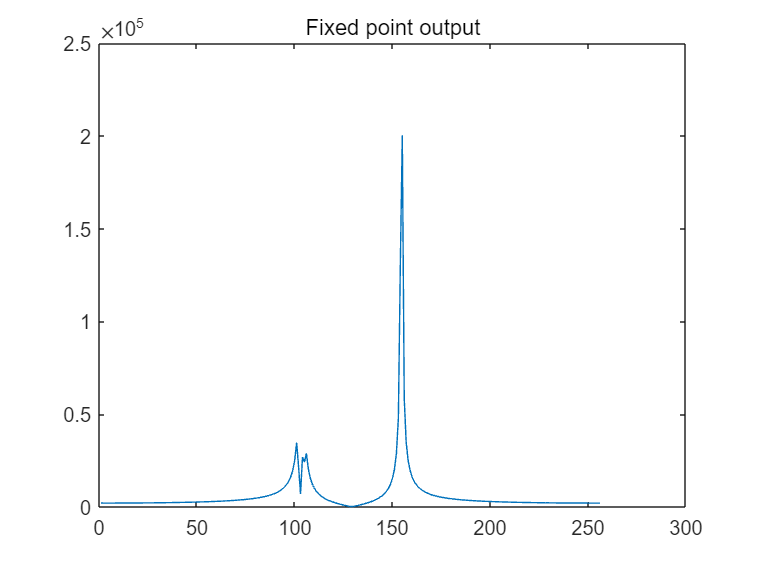

plot(x,fftshift(abs(fix_s)))
title("Fixed point output")

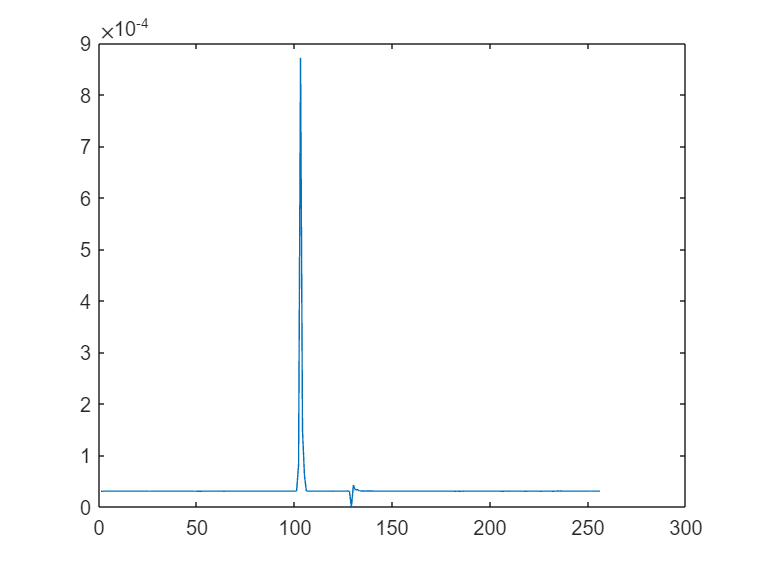

plot(x,fftshift(abs(s ./ fix_s)))

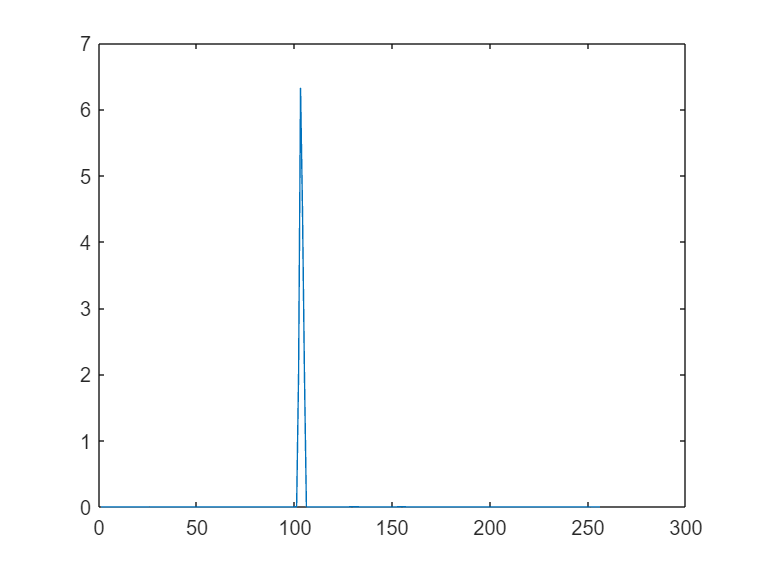

plot(x,fftshift(abs(s - 3.05e-5 * fix_s)))

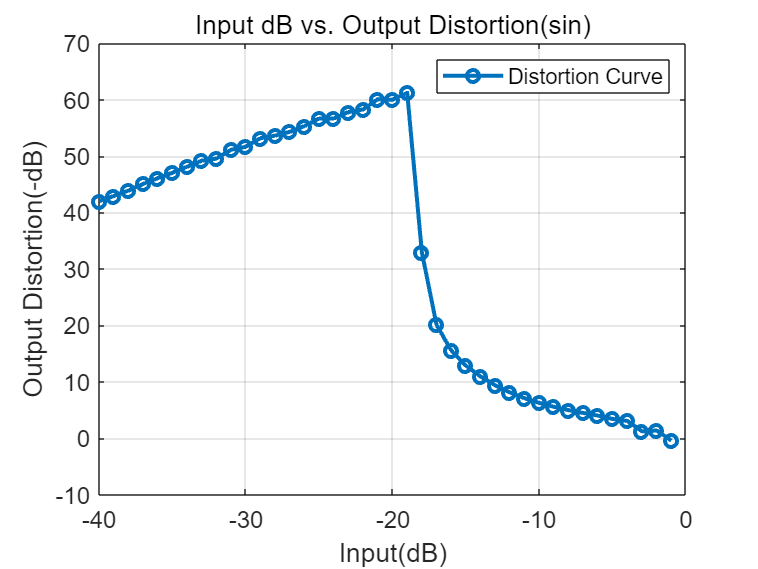

% Q15 256 0
input_dB = [-40.000000, -39.000000, -38.000000, -37.000000, -36.000000, -35.000000, -34.000000, -33.000000, -32.000000, -31.000000, ...
            -30.000000, -29.000000, -28.000000, -27.000000, -26.000000, -25.000000, -24.000000, -23.000000, -22.000000, -21.000000, ...
            -20.000000, -19.000000, -18.000000, -17.000000, -16.000000, -15.000000, -14.000000, -13.000000, -12.000000, -11.000000, ...
            -10.000000, -9.000000, -8.000000, -7.000000, -6.000000, -5.000000, -4.000000, -3.000000, -2.000000, -1.000000];

output_distortion = [41.997972, 42.916255, 43.873689, 45.053550, 46.076308, 47.035422, 48.100829, 49.182415, 49.544126, 51.112291, ...
                     51.632943, 53.157891, 53.620396, 54.279586, 55.300123, 56.634228, 56.638215, 57.786687, 58.254830, 60.065953, ...
                     59.966564, 61.201501, 32.961791, 20.116165, 15.567293, 12.875134, 10.968552, 9.403446, 8.140140, 7.118243, ...
                     6.282537, 5.590997, 5.005899, 4.499329, 4.031920, 3.440235, 3.096224, 1.262581, 1.400183, -0.382769];

% Plot
figure;
plot(input_dB, output_distortion, '-o', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
xlabel('Input(dB)');
ylabel('Output Distortion(-dB)');
title('Input dB vs. Output Distortion(sin)');
legend('Distortion Curve');
set(gca, 'FontSize', 12);

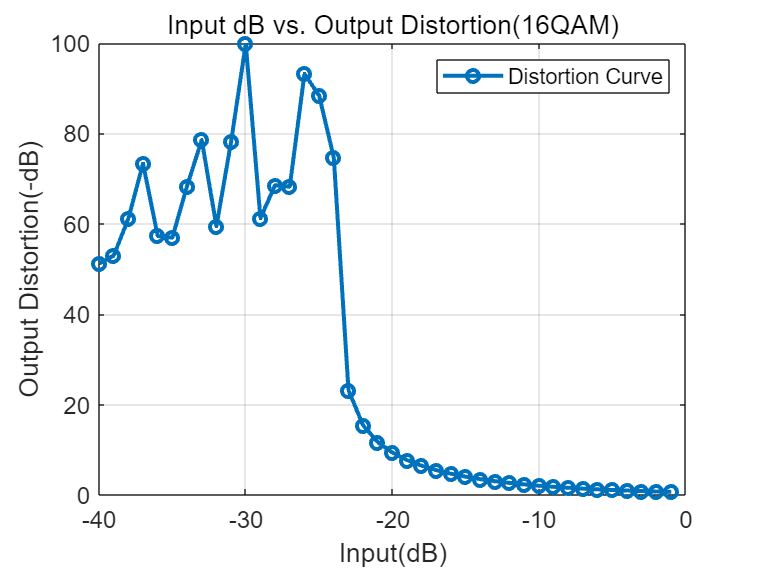

% Q15 256 1
output_distortion = [51.211265,52.952551,61.136931,73.348230,57.302965,56.930052,68.342306,78.552191,59.442451,78.135786,99.851159,61.247811,68.525837,68.226933,93.185156,88.402192,74.657616,23.171661,15.359907,11.673667,9.340019,7.684430,6.435273,5.455687,4.666980,4.019739,3.480917,3.027335,2.642123,2.312634,2.029153,1.784069,1.571318,1.385997,1.224098,1.082305,0.957854,0.848420,0.752035,0.667025,];
% Plot
figure;
plot(input_dB, output_distortion, '-o', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
xlabel('Input(dB)');
ylabel('Output Distortion(-dB)');
title('Input dB vs. Output Distortion(16QAM)');
legend('Distortion Curve');
set(gca, 'FontSize', 12);

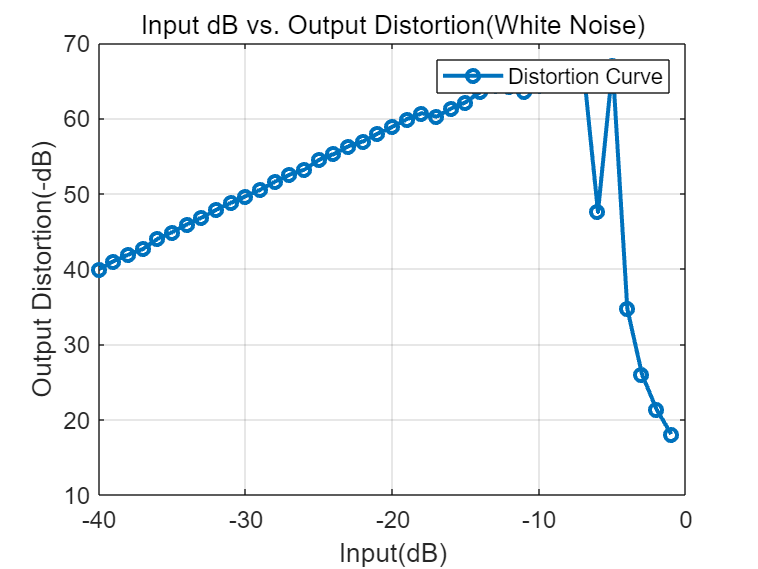

% Q15 256 2
% Data from res_256
input_dB = [-40, -39, -38, -37, -36, -35, -34, -33, -32, -31, -30, -29, -28, -27, -26, -25, -24, -23, -22, -21, -20, -19, -18, -17, -16, -15, -14, -13, -12, -11, -10, -9, -8, -7, -6, -5, -4, -3, -2, -1];
output_distortion = [39.982551, 41.042453, 41.904740, 42.658240, 44.005406, 44.893851, 45.938863, 46.835220, 47.854002, 48.800906, 49.653981, 50.532642, 51.602066, 52.539785, 53.187415, 54.498550, 55.271168, 56.294843, 56.959392, 57.967173, 58.875388, 59.911682, 60.687257, 60.220175, 61.310106, 62.168326, 63.536596, 64.430357, 64.248278, 63.536376, 64.319659, 65.071102, 66.004712, 66.855385, 47.567523, 66.959282, 34.740988, 26.019447, 21.323256, 18.051264];

% Plot
figure;
plot(input_dB, output_distortion, '-o', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
xlabel('Input(dB)');
ylabel('Output Distortion(-dB)');
title('Input dB vs. Output Distortion(White Noise)');
legend('Distortion Curve');
set(gca, 'FontSize', 12);

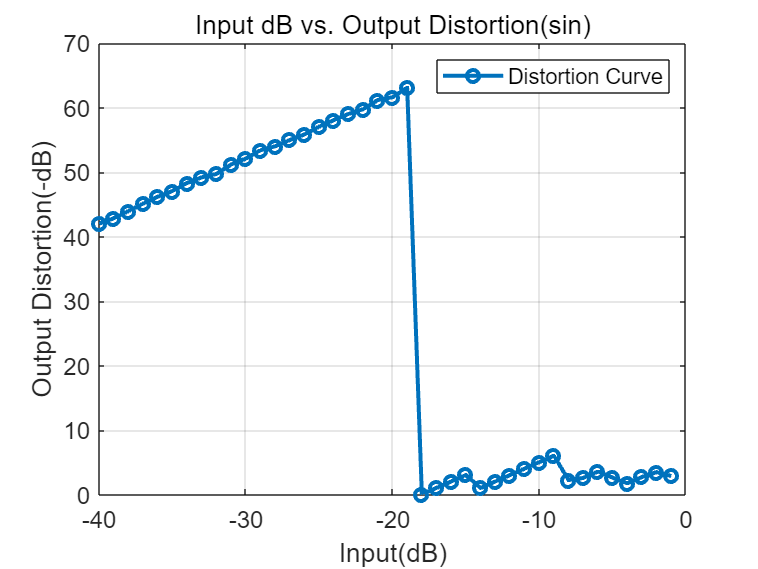

% Q17 256 0
output_distortion = [42.027751,42.851702,43.974178,45.115787,46.187080,47.077691,48.319035,49.191252,49.719407,51.178898,52.101036,53.393891,54.012121,54.984133,55.838019,57.053212,58.070090,59.018883,59.756426,61.177489,61.611730,63.091332,0.077791,1.077625,2.078292,3.078856,1.067945,2.067989,3.067289,4.069705,5.067659,6.067731,2.296466,2.627752,3.627190,2.664606,1.773651,2.773641,3.525549,2.928891];
% Plot
figure;
plot(input_dB, output_distortion, '-o', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
xlabel('Input(dB)');
ylabel('Output Distortion(-dB)');
title('Input dB vs. Output Distortion(sin)');
legend('Distortion Curve');
set(gca, 'FontSize', 12);

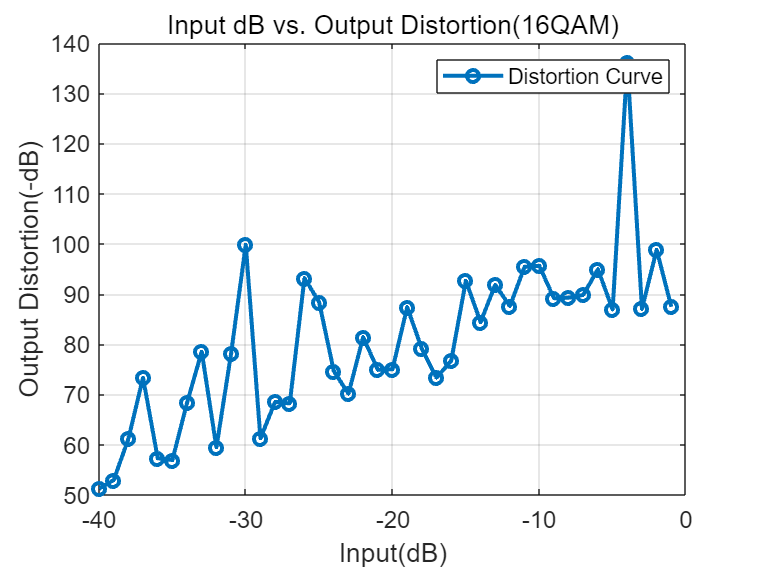

% Q17 256 1
output_distortion = [51.211265,52.952551,61.136931,73.348230,57.302965,56.930052,68.342306,78.552191,59.442451,78.135786,99.851159,61.247811,68.525837,68.226933,93.185156,88.402192,74.657616,70.133970,81.428264,74.896022,75.035023,87.393119,79.115440,73.348230,76.696969,92.670444,84.398559,91.849833,87.587335,95.425586,95.634091,89.166969,89.279488,89.829140,94.941292,86.904901,136.073448,87.047364,98.836622,87.461107];
% Plot
figure;
plot(input_dB, output_distortion, '-o', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
xlabel('Input(dB)');
ylabel('Output Distortion(-dB)');
title('Input dB vs. Output Distortion(16QAM)');
legend('Distortion Curve');
set(gca, 'FontSize', 12);

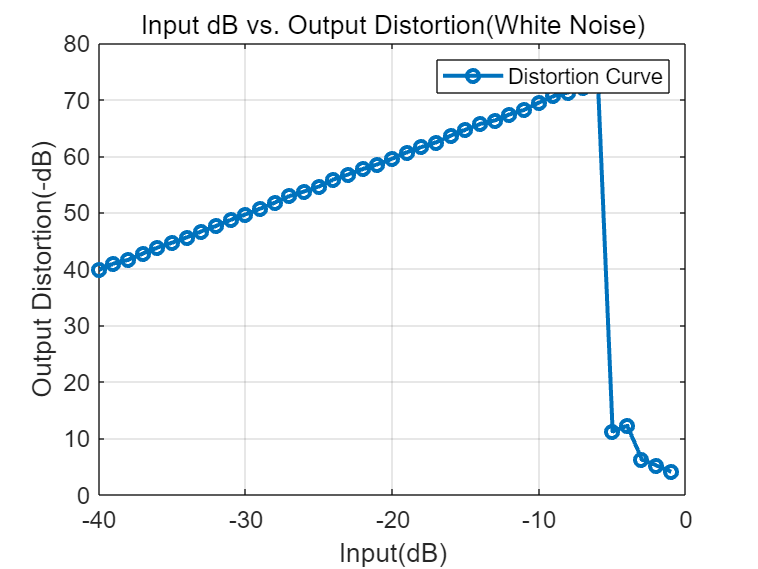

% Q17 256 2
output_distortion = [39.835732,40.965037,41.615042,42.750417,43.786250,44.675474,45.622563,46.683841,47.637620,48.714944,49.676397,50.698019,51.784803,52.932116,53.741606,54.620349,55.862140,56.757050,57.717680,58.551820,59.549182,60.680688,61.615578,62.455311,63.641725,64.684270,65.695714,66.333967,67.386057,68.188475,69.468898,70.642472,71.280307,72.160889,73.102270,11.226739,12.226759,6.236966,5.195801,4.087311];
% Plot
figure;
plot(input_dB, output_distortion, '-o', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
xlabel('Input(dB)');
ylabel('Output Distortion(-dB)');
title('Input dB vs. Output Distortion(White Noise)');
legend('Distortion Curve');
set(gca, 'FontSize', 12);